%% System Parameters
N = 20;          % Number of quadrature nodes (for Gauss-Hermite integration)
SNR = 1;         % Signal-to-Noise Ratio
array = [2, 4, 8, 16, 32, 64, 128, 256];
% M = 16;          % Size of the PAM constellation (number of symbols)
d = 2;           % Distance parameter (spacing between constellation points)
R = 0.5;         % Communication rate

%% Compute Gauss-Hermite Nodes and Weights
% These are used for numerical integration over a Gaussian density.
[nodes, weights] = GaussHermite_Locations_Weights(N);

total_times_old = zeros(4, length(array));
total_times_new = zeros(4, length(array));

for i = 1:length(array)

    M = array(i);

    %% Generate and Normalize PAM Constellation
    % Create a PAM constellation with M symbols and spacing d.
    X = generatePAMConstellation(M, d);
    % Normalize the constellation so that its average energy is 1.
    X = X / sqrt(mean(X.^2));

    %% Initialize the Probability Distribution for Constellation Symbols
    % Create a column vector where each symbol has equal probability (1/M).
    Q = repmat(1/M, 1, M);
    Q = Q';

    %% Define the Gaussian Function
    G = @(z) exp(-abs(z).^2) / pi;

    %% Create Required Matrices for Computation
    pi_matrix = createPiMatrix(M, N, weights);
    z_matrix = createComplexNodesMatrix(nodes);
    g_matrix = createGMatrix(X, z_matrix, SNR, G);

    rho = 0.5;
    n = 1e2;
    T = zeros(1,4);
    T_old = zeros(1,4);

    for j = 1:n
        [m, mp, m2p, times_old] = F0_matrix(Q, pi_matrix, g_matrix, rho);
        [F0, dF0, d2F0, times_new] = derivativesE0(Q, pi_matrix, g_matrix, rho);
        T = T + times_new;
        T_old = T_old + times_old;

    end
    total_times_new(:, i) = T';
    total_times_old(:, i) = T_old';

    disp(M);
end

     2

     4

     8

    16

    32

    64

   128

   256




disp(total_times_old);

   0.009894958333333   0.009288625000000   0.020121083333333   0.057648333333333   0.279459000000000   0.771418791666667   2.737444291666665  12.104125500000002
   0.000968916666667   0.000883125000000   0.001277125000000   0.002634291666667   0.019338708333333   0.044594750000000   0.112176416666667   0.428100791666667
   0.002054000000000   0.002139375000000   0.004093833333333   0.011373500000000   0.046972750000000   0.196094291666667   0.540394166666666   2.714618458333333
   0.003215208333333   0.003838708333333   0.008014833333333   0.019011875000000   0.088921458333333   0.356976916666667   1.145872583333333   5.042201625000000



disp(total_times_new);

   0.010452083333333   0.008400166666667   0.018049541666667   0.054447416666667   0.269123333333333   0.740787666666667   2.562028166666667  10.931209750000001
   0.000707333333333   0.000733166666667   0.001096583333333   0.002994958333333   0.013854791666667   0.040972041666667   0.094691416666667   0.406554000000000
   0.004578541666667   0.004817583333333   0.009158916666667   0.022364958333333   0.120132916666667   0.425036291666667   1.176928708333333   5.668229458333335
   0.013108666666667   0.015597916666667   0.032054000000000   0.080965708333333   0.501580333333333   1.207045500000000   3.655463708333334  16.789672458333339



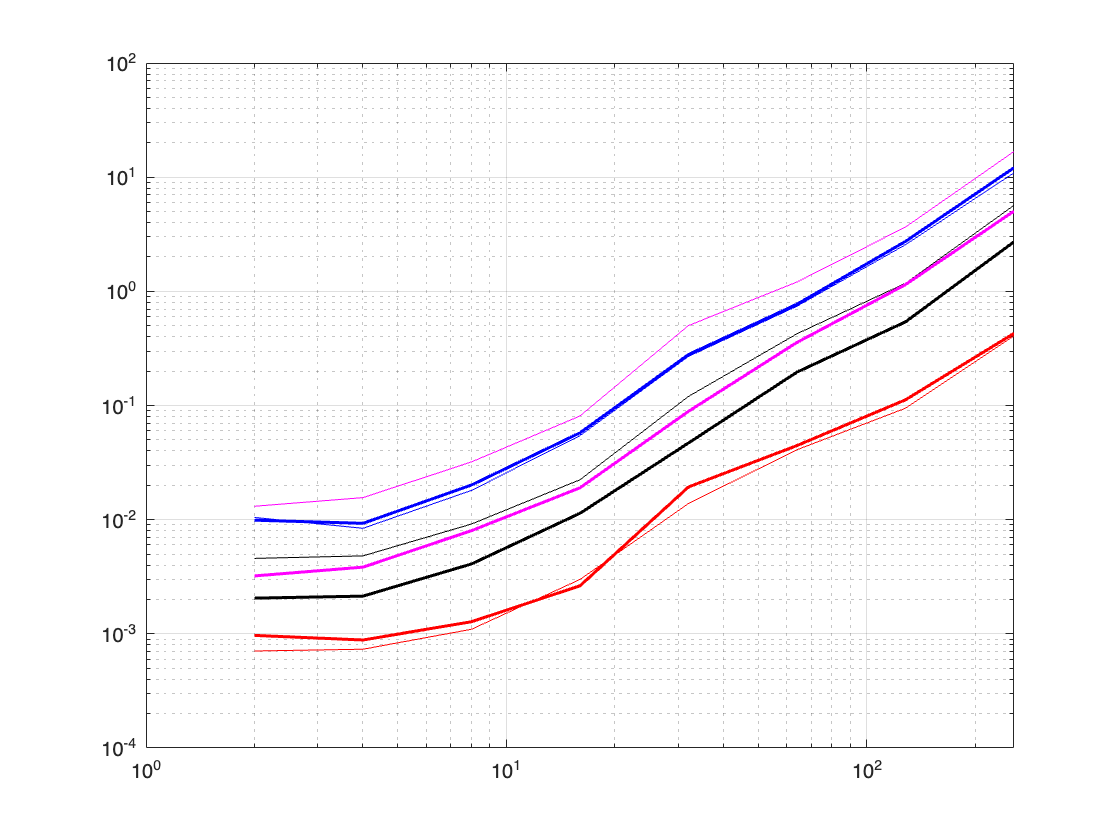



figure;
loglog(array, total_times_old(1,:),'Color', 'b', 'LineWidth', 1.5);
hold on;
loglog(array, total_times_new(1,:),'Color', 'b');

loglog(array, total_times_old(2,:),'Color', 'r', 'LineWidth', 1.5);
loglog(array, total_times_new(2,:),'Color', 'r');

loglog(array, total_times_old(3,:),'Color', 'k', 'LineWidth', 1.5);
loglog(array, total_times_new(3,:),'Color', 'k');

loglog(array, total_times_old(4,:),'Color', 'm', 'LineWidth', 1.5);
loglog(array, total_times_new(4,:),'Color', 'm');
grid on;
hold off;

%% System Parameters
Nset = 1:20;                                   % Quadrature nodes: 1, 2, ..., 20
% M_array = [16, 32, 64, 128, 256, 512];     % PAM constellation sizes from 2 up to 1024
M_array = 16:4:256;
SNR = 1;                                       % Signal-to-Noise Ratio
d = 2;                                         % Distance parameter (spacing between constellation points)
R = 0.5;                                       % Communication rate (available if needed)

%% Preallocate arrays for execution times
numMetrics = 4;
total_times_old = zeros(numMetrics, length(M_array), length(Nset));
total_times_new = zeros(numMetrics, length(M_array), length(Nset));

nIter = 10;  % Number of iterations for averaging execution time

%% Main Simulation Loop
for idxN = 1:length(Nset)
    N = Nset(idxN);
    
    % Compute Gauss-Hermite Nodes and Weights for current N.
    % (Ensure your function handles N=1 gracefully.)
    [nodes, weights] = GaussHermite_Locations_Weights(N);
    
    % Compute the complex nodes matrix once per N (depends only on nodes)
    z_matrix = createComplexNodesMatrix(nodes);
    
    for idxM = 1:length(M_array)
        M = M_array(idxM);
        
        %% Generate and Normalize PAM Constellation
        X = generatePAMConstellation(M, d);
        X = X / sqrt(mean(X.^2));  % Normalize constellation to unit average energy
        
        %% Initialize the Probability Distribution for Constellation Symbols
        Q = repmat(1/M, M, 1);  % Uniform distribution for each symbol
        
        %% Define the Gaussian Function
        G = @(z) exp(-abs(z).^2) / pi;
        
        %% Create Required Matrices for Computation
        pi_matrix = createPiMatrix(M, N, weights);
        g_matrix = createGMatrix(X, z_matrix, SNR, G);
        
        rho = 0.5;
        T_new = zeros(1, numMetrics);
        T_old = zeros(1, numMetrics);
        
        %% Run simulation nIter times to average execution times
        for j = 1:nIter
            % The functions below are assumed to return 4 timing metrics in the 4th output.
            [~, ~, ~, times_old] = F0_matrix(Q, pi_matrix, g_matrix, rho);
            [~, ~, ~, times_new] = derivativesE0(Q, pi_matrix, g_matrix, rho);
            T_new = T_new + times_new;
            T_old = T_old + times_old;
        end
        
        % Store average execution times for this combination of M and N
        total_times_new(:, idxM, idxN) = T_new' / nIter;
        total_times_old(:, idxM, idxN) = T_old' / nIter;

        % Progress update
        disp(['Completed: M = ', num2str(M), ', N = ', num2str(N)]);
    end
end

Completed: M = 16, N = 1
Completed: M = 20, N = 1
Completed: M = 24, N = 1
Completed: M = 28, N = 1
Completed: M = 32, N = 1
Completed: M = 36, N = 1
Completed: M = 40, N = 1
Completed: M = 44, N = 1
Completed: M = 48, N = 1
Completed: M = 52, N = 1
Completed: M = 56, N = 1
Completed: M = 60, N = 1
Completed: M = 64, N = 1
Completed: M = 68, N = 1
Completed: M = 72, N = 1
Completed: M = 76, N = 1
Completed: M = 80, N = 1
Completed: M = 84, N = 1
Completed: M = 88, N = 1
Completed: M = 92, N = 1
Completed: M = 96, N = 1
Completed: M = 100, N = 1
Completed: M = 104, N = 1
Completed: M = 108, N = 1
Completed: M = 112, N = 1
Completed: M = 116, N = 1
Completed: M = 120, N = 1
Completed: M = 124, N = 1
Completed: M = 128, N = 1
Completed: M = 132, N = 1
Completed: M = 136, N = 1
Completed: M = 140, N = 1
Completed: M = 144, N = 1
Completed: M = 148, N = 1
Completed: M = 152, N = 1
Completed: M = 156, N = 1
Completed: M = 160, N = 1
Completed: M = 164, N = 1
Completed: M = 168, N = 1
Complet


disp('Old Method Execution Times:');

Old Method Execution Times:


disp(total_times_old);


(:,:,1) =

   1.0e-03 *

   0.013170833333333   0.013091666666667   0.106591666666667   0.034537500000000   0.024500000000000   0.067462500000000   0.041166666666667   0.048220833333333   0.054100000000000   0.075350000000000   0.067720833333333   0.103770833333333   0.117612500000000   0.076220833333333   0.076129166666667   0.091362500000000   0.068929166666667   0.071816666666667   0.086008333333333   0.125808333333333   0.119595833333333   0.107300000000000   0.111333333333333   0.114175000000000   0.093866666666667   0.122187500000000   0.129100000000000   0.146516666666667   0.117433333333333   0.117958333333333   0.136295833333333   0.130754166666667   0.136666666666667   0.135191666666667   0.150554166666667   0.153016666666667   0.176258333333333   0.174912500000000   0.191791666666667   0.231150000000000   0.229912500000000   0.200758333333333   0.246383333333333   0.293075000000000   0.242412500000000   0.260304166666667   0.258037500000000   0.265612500000000   0.281087500

disp('New Method Execution Times:');

New Method Execution Times:


disp(total_times_new);


(:,:,1) =

   0.000034395833333   0.000013066666667   0.000026150000000   0.000031229166667   0.000021350000000   0.000071866666667   0.000041954166667   0.000060279166667   0.000051212500000   0.000068870833333   0.000085645833333   0.000114620833333   0.000120250000000   0.000073804166667   0.000072720833333   0.000083112500000   0.000055558333333   0.000076825000000   0.000071316666667   0.000126604166667   0.000123804166667   0.000096433333333   0.000110020833333   0.000104883333333   0.000079170833333   0.000108962500000   0.000108391666667   0.000125737500000   0.000109545833333   0.000106133333333   0.000112675000000   0.000112145833333   0.000117062500000   0.000120054166667   0.000122420833333   0.000141895833333   0.000139266666667   0.000144295833333   0.000153416666667   0.000210354166667   0.000181550000000   0.000167670833333   0.000252204166667   0.000256629166667   0.000223783333333   0.000241204166667   0.000234579166667   0.000228037500000   0.000226412500000   0.000

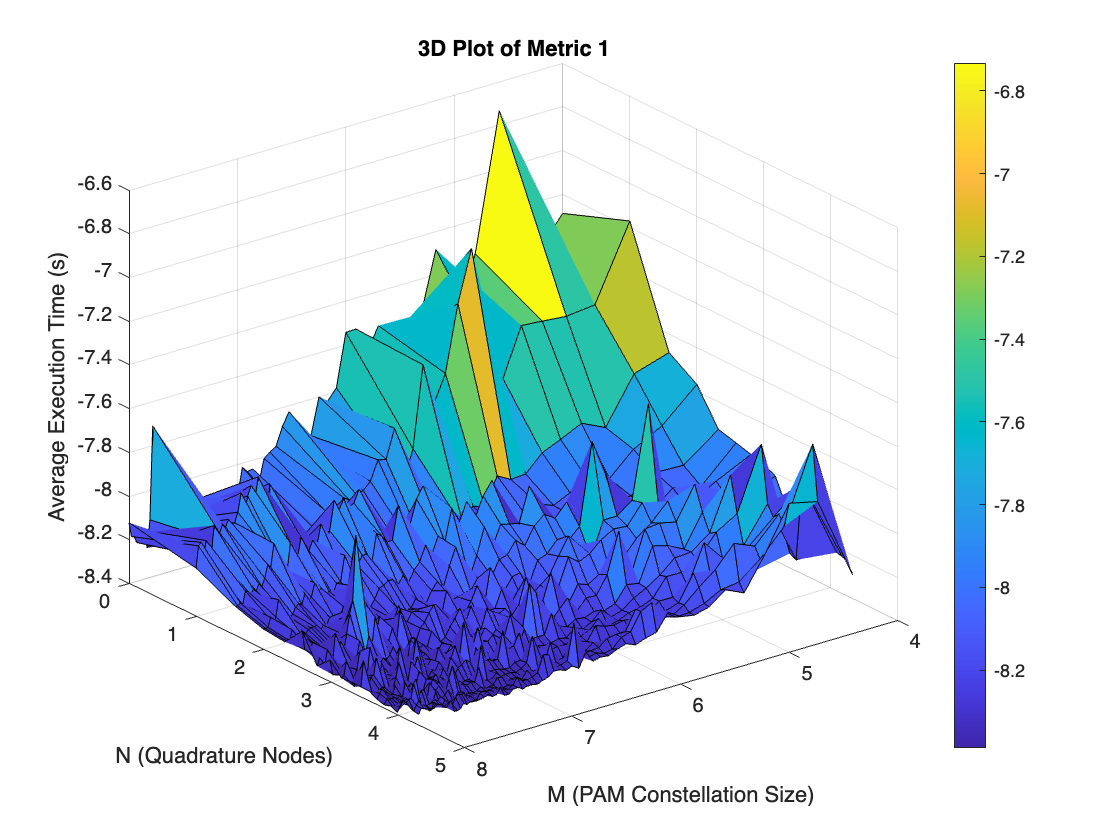

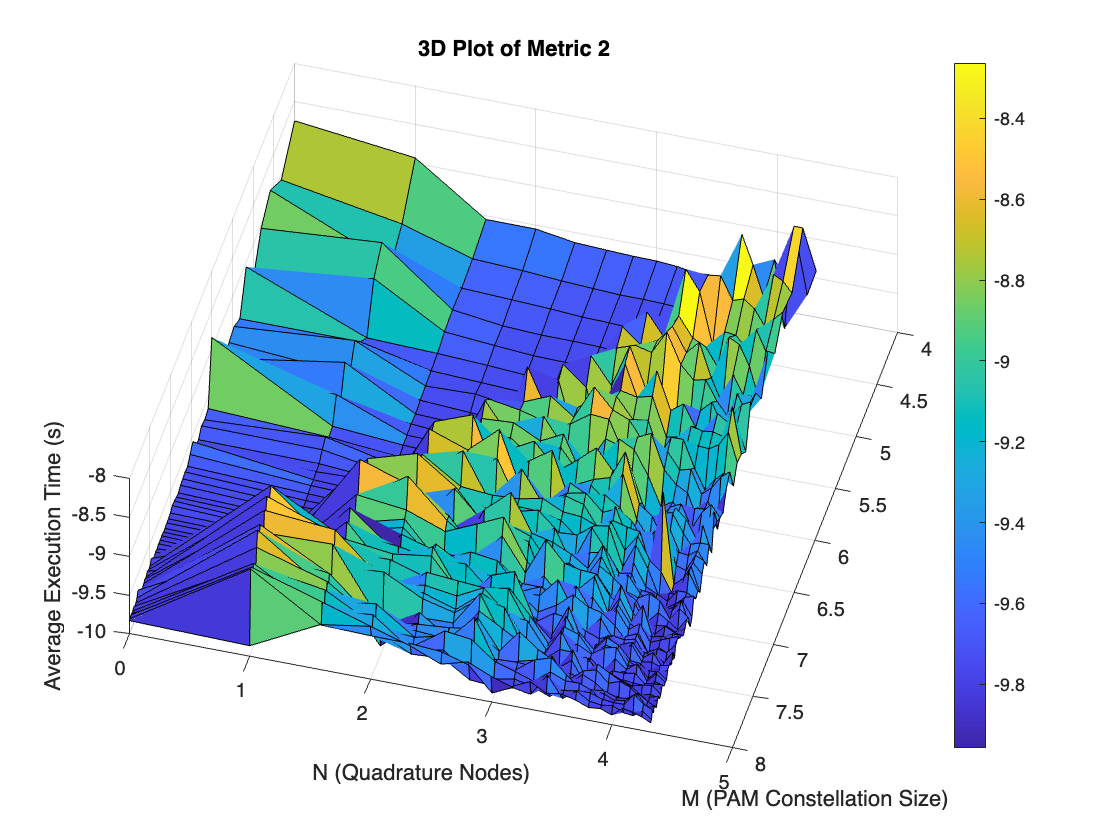

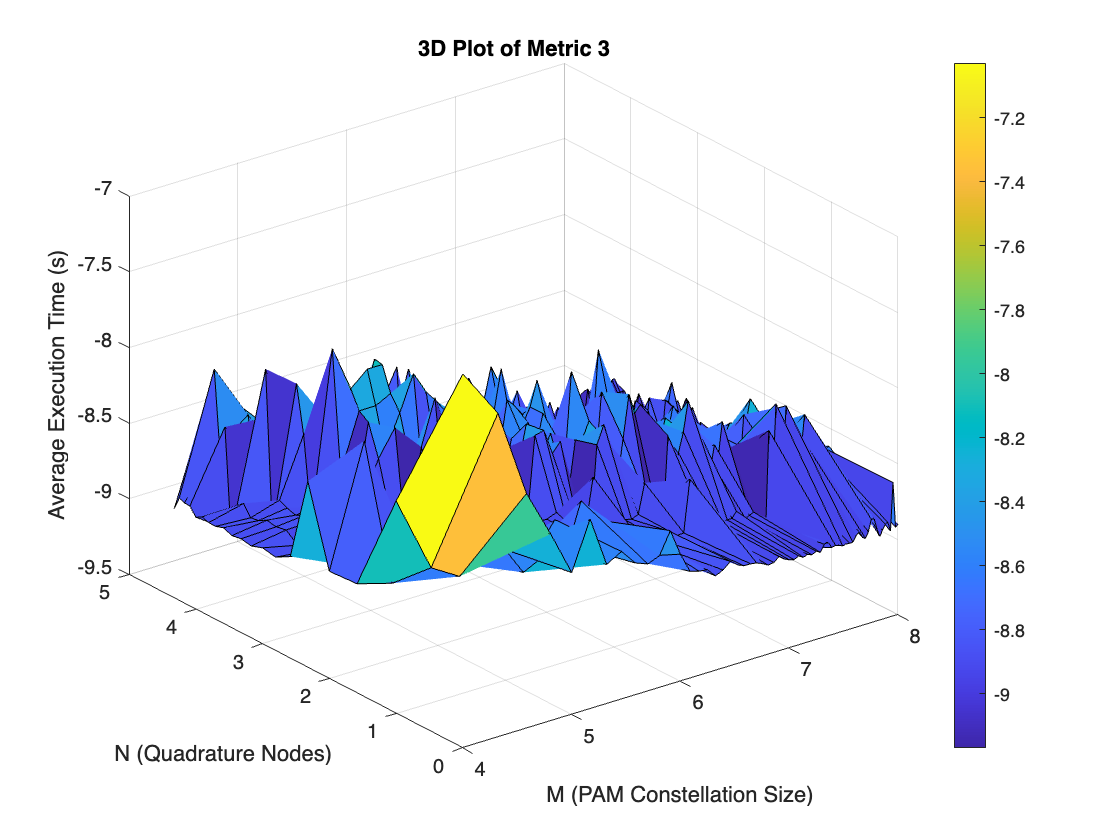

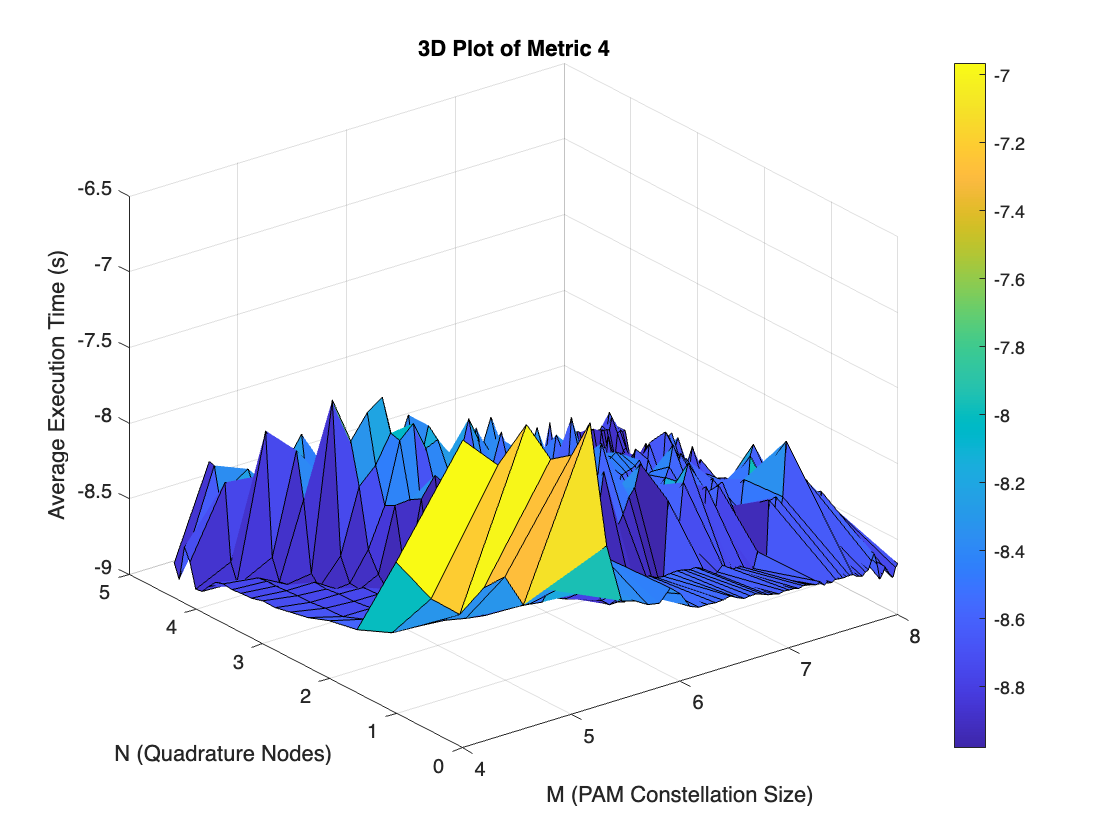


%% Create Meshgrid for Plotting
% Meshgrid for M (x-axis) and N (y-axis)
[M_grid, N_grid] = meshgrid(M_array, Nset);

%% 3D Surface Plots for the 4 Metrics (New Method)
for metric = 1:numMetrics
    % Extract the average execution times for the current metric.
    % squeeze converts from [1 x length(M_array) x length(Nset)] to [length(M_array) x length(Nset)].
    % Then, we transpose so that the first dimension corresponds to Nset.
    time_metric = squeeze(total_times_old(metric, :, :))';  
    time_metric = time_metric ./ ((M_grid.^2).*(N_grid.^2));

    figure;
    surf(log2(M_grid), log2(N_grid), log10(time_metric));
    xlabel('M (PAM Constellation Size)');
    ylabel('N (Quadrature Nodes)');
    zlabel('Average Execution Time (s)');
    title(['3D Plot of Metric ', num2str(metric)]);
    colorbar;
end

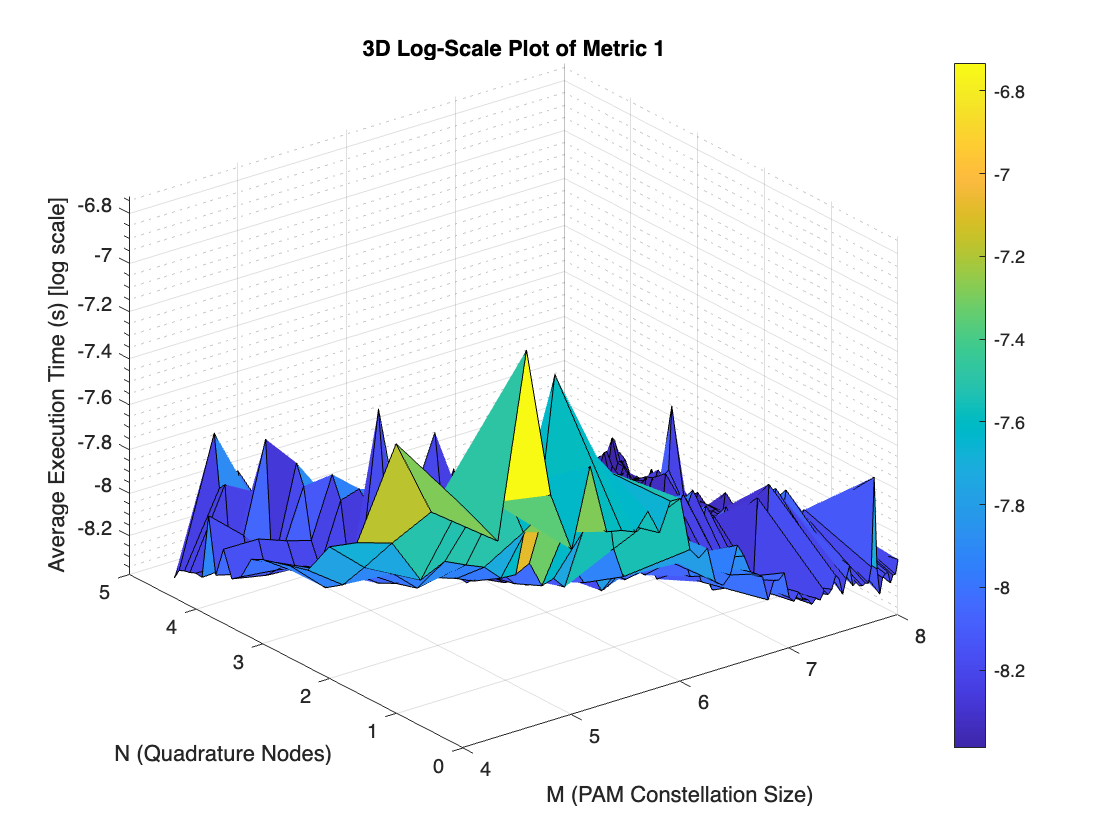

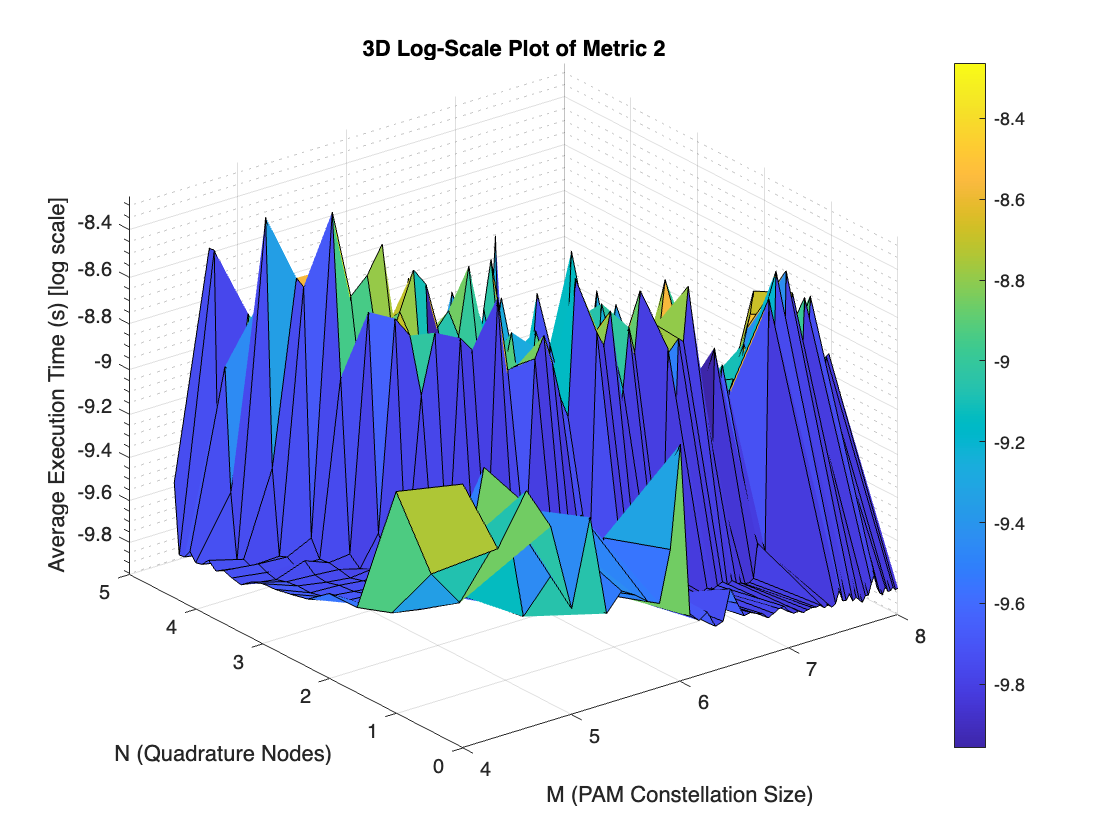

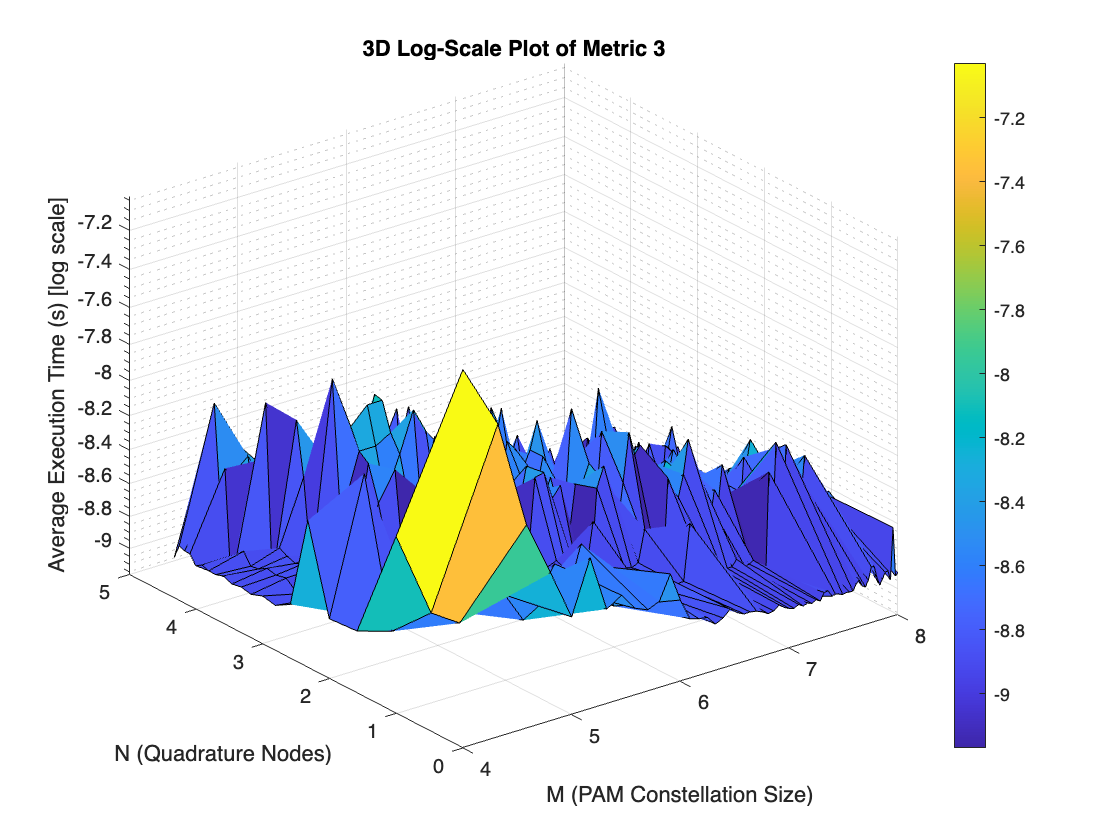

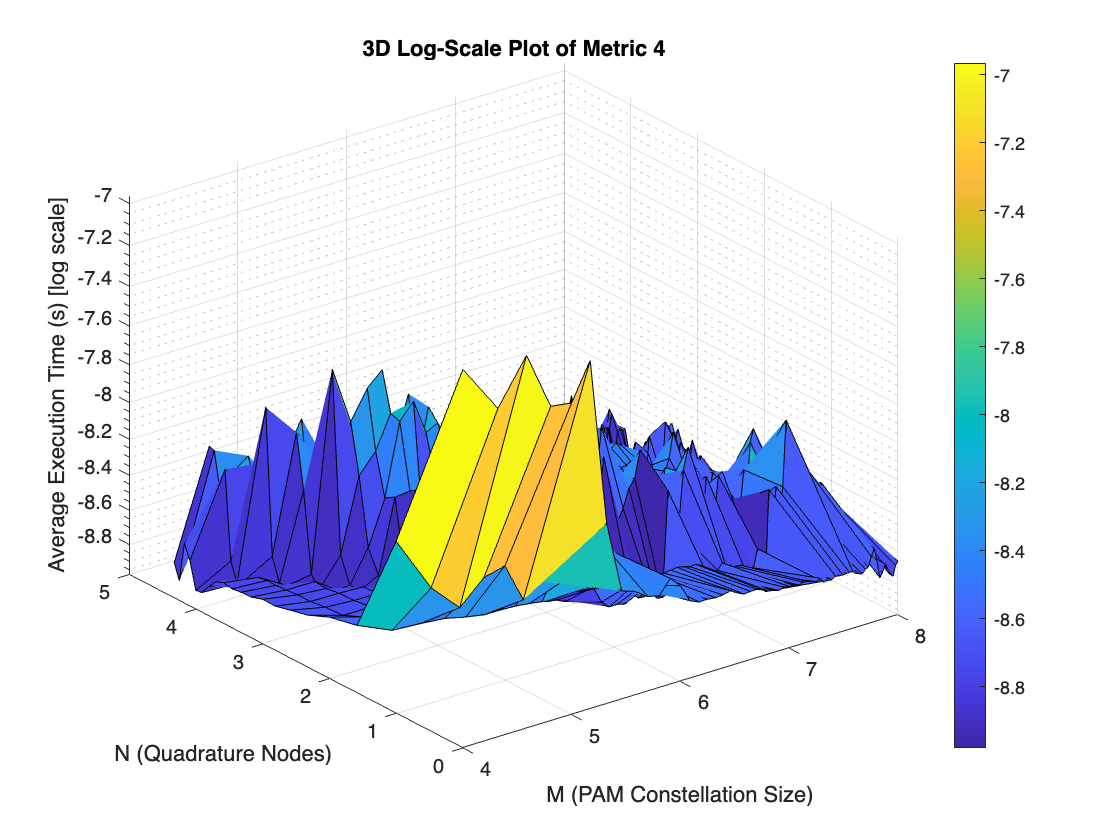


for metric = 1:numMetrics
    % Extract the average execution times for the current metric.
    % squeeze converts from [1 x length(M_array) x length(Nset)] to [length(M_array) x length(Nset)],
    % and then we transpose so that the first dimension corresponds to Nset.
    time_metric = squeeze(total_times_old(metric, :, :))';  
    time_metric = time_metric ./ ((M_grid.^2).*(N_grid.^2));
    
    figure;
    surf(log2(M_grid), log2(N_grid), log10(time_metric));
    
    % Set the Z-axis (execution time) to log scale.
    set(gca, 'ZScale', 'log'); 
    
    xlabel('M (PAM Constellation Size)');
    ylabel('N (Quadrature Nodes)');
    zlabel('Average Execution Time (s) [log scale]');
    title(['3D Log-Scale Plot of Metric ', num2str(metric)]);
    colorbar;
end

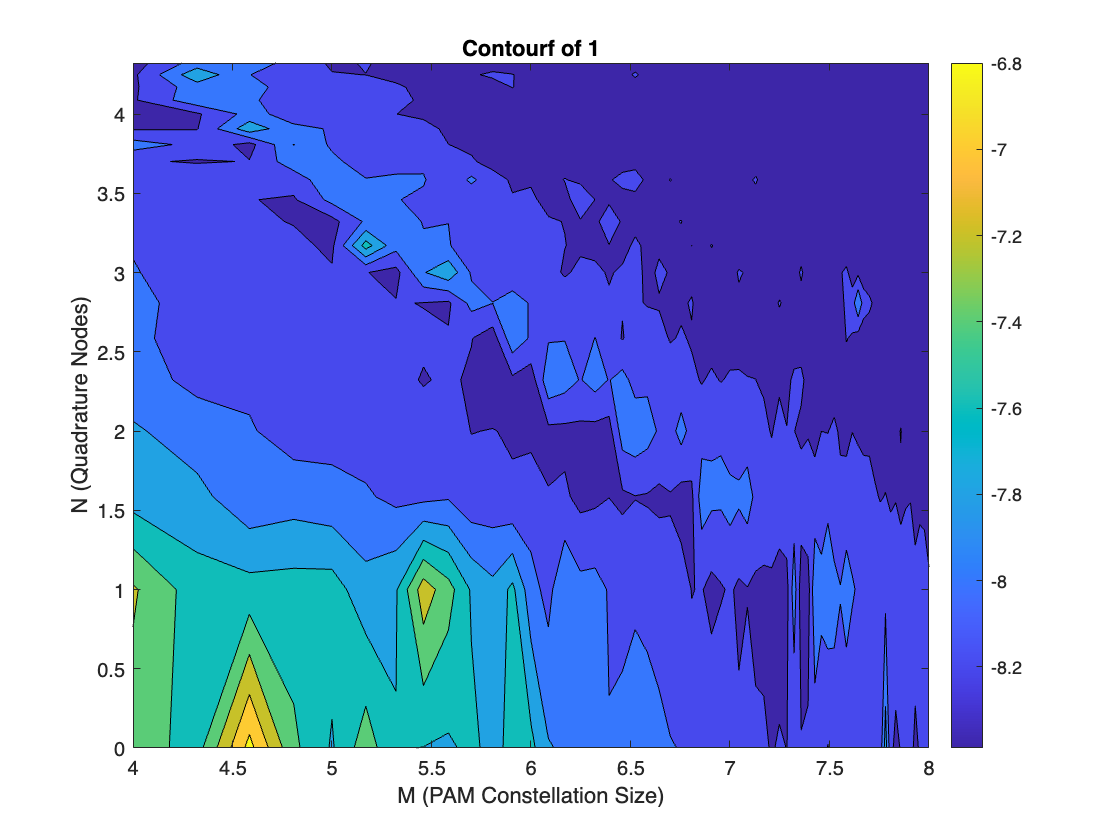

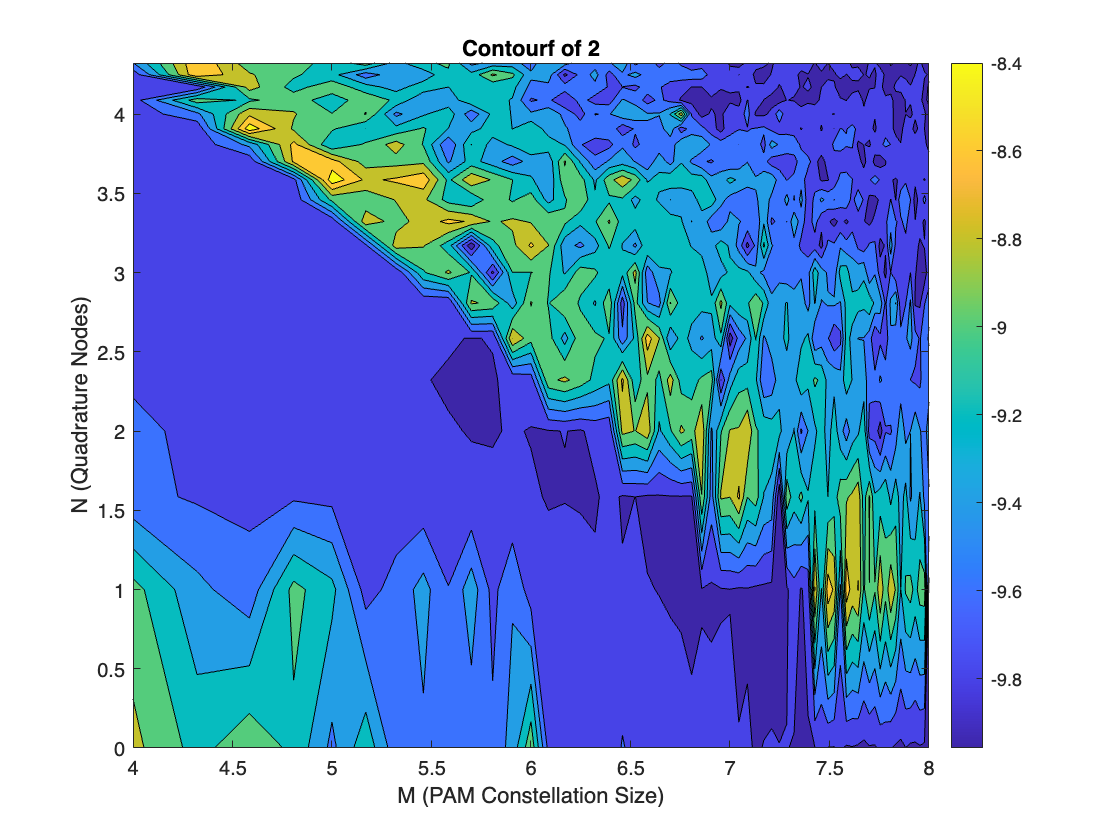

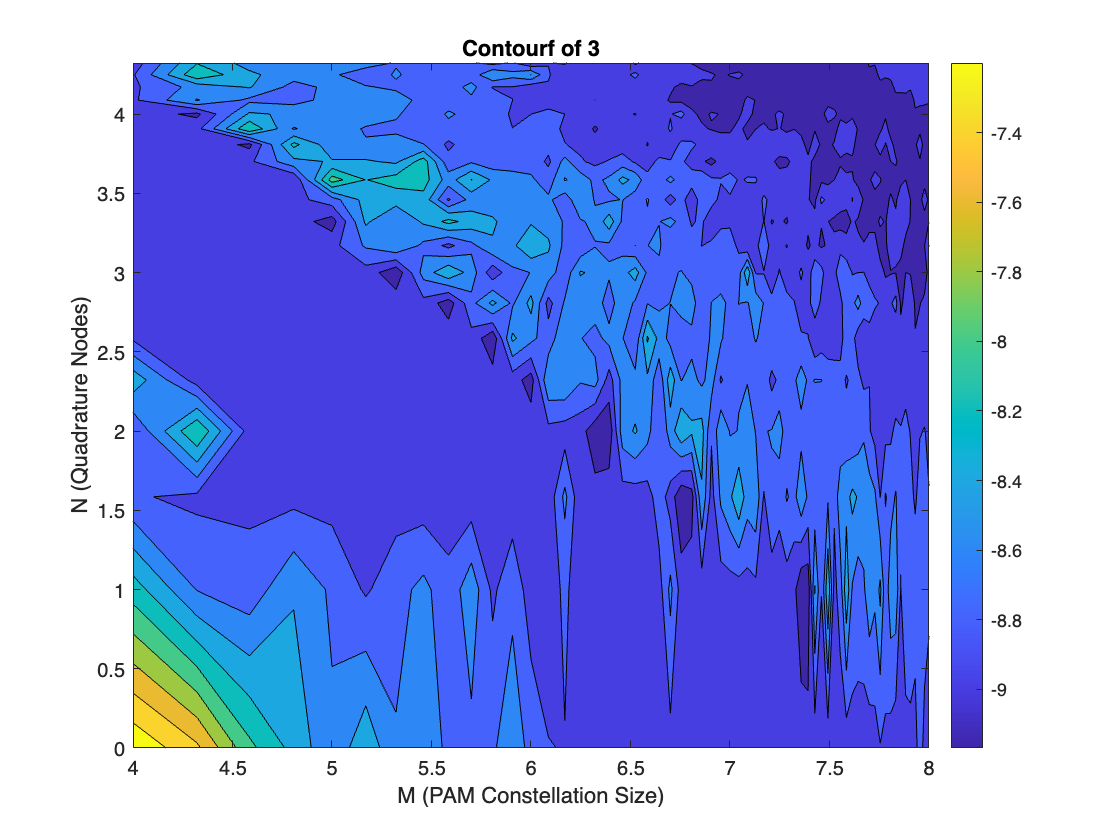

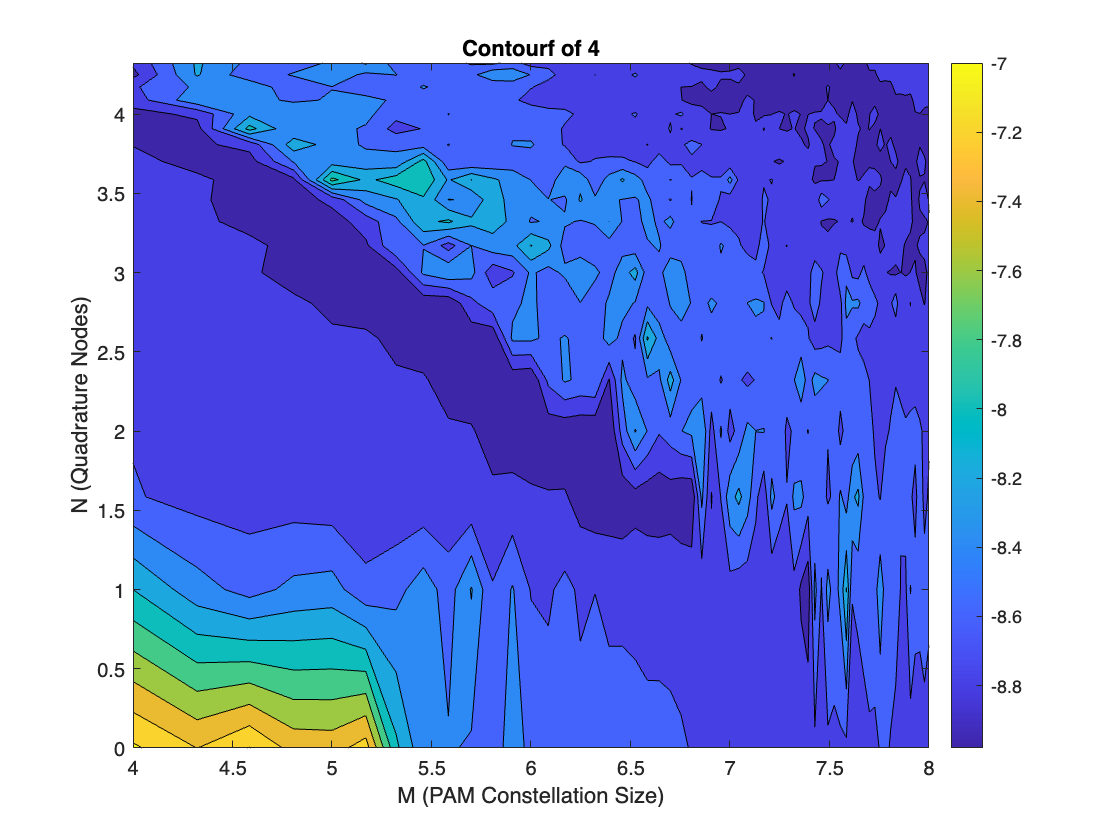


for metric = 1:numMetrics
    % Extract the average execution times for the current metric.
    % squeeze converts from [1 x length(M_array) x length(Nset)] to [length(M_array) x length(Nset)],
    % and then we transpose so that the first dimension corresponds to Nset.
    time_metric = squeeze(total_times_old(metric, :, :))';
    time_metric = time_metric ./ ((M_grid.^2).*(N_grid.^2));
    
    figure;
    contourf(log2(M_grid), log2(N_grid), log10(time_metric));
    
    xlabel('M (PAM Constellation Size)');
    ylabel('N (Quadrature Nodes)');
    zlabel('Average Execution Time (s) [log scale]');
    title(['Contourf of ', num2str(metric)]);
    colorbar;
end

## System Parameters

tic;
N = 2;          % Number of quadrature nodes (for Gauss-Hermite integration)
SNR = 1;         % Signal-to-Noise Ratio
M = 2;
d = 2;           % Distance parameter (spacing between constellation points)
R = 0.5;         % Communication rate

rho = 0.5;

%% Compute Gauss-Hermite Nodes and Weights
% These are used for numerical integration over a Gaussian density.
[nodes, weights] = GaussHermite_Locations_Weights(N);


    %% Generate and Normalize PAM Constellation
    % Create a PAM constellation with M symbols and spacing d.
    X = generatePAMConstellation(M, d);
    % Normalize the constellation so that its average energy is 1.
    X = X / sqrt(mean(X.^2));

    %% Initialize the Probability Distribution for Constellation Symbols
    % Create a column vector where each symbol has equal probability (1/M).
    Q = repmat(1/M, 1, M);
    Q = Q';

    %% Define the Gaussian Function
    G = @(z) exp(-abs(z).^2) / pi;

    %% Create Required Matrices for Computation
    pi_matrix = createPiMatrix(M, N, weights);
    z_matrix = createComplexNodesMatrix(nodes);
    g_matrix = createGMatrix(X, z_matrix, SNR, G);

    disp(pi_matrix);

   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397449                   0                   0                   0                   0
                   0                   0                   0                   0   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397449



    disp(g_matrix);

   0.117099663048638   0.117099663048638   0.117099663048638   0.117099663048638   0.000126767353884   0.036286744811575   0.000126767353884   0.036286744811575
   0.036286744811575   0.000126767353884   0.036286744811575   0.000126767353884   0.117099663048638   0.117099663048638   0.117099663048638   0.117099663048638



    disp(Q);

   0.500000000000000
   0.500000000000000



    [F0, F0p, F0pp, times_old] = F0_matrix(Q, pi_matrix, g_matrix, rho)

F0 =    0.782308865869893


F0p =   -0.377581412634334


F0pp =    0.208294507723129


times_old = 1.0e-03 *

   0.227083333333333   0.014875000000000   0.036208333333333   0.042166666666667


    toc

Elapsed time is 0.031015 seconds.
